clear all; close all; clc

## Homework 2

- Which is more probable when rolling 2 six-sided dice: rolling two 1s or rolling a sum of seven? What is the ratio of probabilities?

To answer this question, I compare the number of combinations possible for each outcome.

In the case of rolling two 1s, there is only 1 possible combination: rolling a 1 for each die.

In the case of rolling a sum of seven, the possible combinations are tabulated below:

**DIE 1        DIE 2        SUM**

1               6               7

2               5               7

3               4               7

4               3               7

5               2               7

6               1               7

There are a total of 6 combinations that yield a sum of seven. Therefore, since there are more ways to get seven than two 1s, the probability of getting a sum of seven is higher.

To compute the ratio of probabilities, I calculate the probability of each outcome. This is done using the following formula:


$$P\left(\textrm{sum}\right)=\frac{\textrm{No}\ldotp \textrm{of}\;\textrm{combinations}\;\textrm{to}\;\textrm{get}\;\textrm{sum}}{\textrm{Total}\;\textrm{no}\ldotp \textrm{of}\;\textrm{combinations}\;\textrm{available}}$$


There are 36 total combinations available.


$$\begin{array}{l}
P\left(2\right)=\frac{1}{36}\\
P\left(7\right)=\frac{6}{36}
\end{array}$$



$$\frac{P\left(2\right)}{P\left(7\right)}=\frac{1}{36}/\frac{6}{36}=\frac{1}{6}$$


The ratio of probabilties is 1/6.

2. Show how to use the convolution operator to determine the probability of the sum of 2 six-sided dice.

I will present both analytical and numerical solutions to this problem. The convolution operator for a discrete distribution is as follows:


$$P_{A+B} \left(x\right)=\sum_z P_A \left(z\right)P_B \left(x-z\right)$$


Analytical solution

For our application, *x *can take the values $2\le x\le 12$.


$$P_{A+B} \left(2\right)=\sum_z P_A \left(z\right)P_B \left(2-z\right)$$


              
$$\begin{array}{l}
=P_A \left(1\right)P_B \left(1\right)\\
=\frac{1}{36}
\end{array}$$



$$P_{A+B} \left(3\right)=\sum_z P_A \left(z\right)P_B \left(3-z\right)$$


              
$$\begin{array}{l}
=P_A \left(1\right)P_B \left(2\right)+P_A \left(2\right)P_B \left(1\right)\\
=\frac{1}{36}+\frac{1}{36}\\
=\frac{2}{36}
\end{array}$$


The rest of the probabilities are summarized in the table below.

***x            *****DIE A                DIE B                        PROBABILITY**

2            (1)                      (1)                            1/36

3            (1,2)                   (2,1)                         2/36

4            (1,2,3)                (3,2,1)                      3/36

5            (1,2,3,4)             (4,3,2,1)                   4/36

6            (1,2,3,4,5)          (5,4,3,2,1)                5/36

7            (1,2,3,4,5,6)       (6,5,4,3,2,1)             6/36

8            (2,3,4,5,6)          (6,5,4,3,2)                5/36

9            (3,4,5,6)             (6,5,4,3)                   4/36

10          (4,5,6)                (6,5,4)                      3/36

11          (5,6)                   (6,5)                         2/36

12          (6)                      (6)                            1/36

I need to check that the probabilities sum to 1:


$$\frac{1+2+3+4+5+6+5+4+3+2+1}{36}=1$$


They do, so this distribution is reasonable.

The results are plotted below.

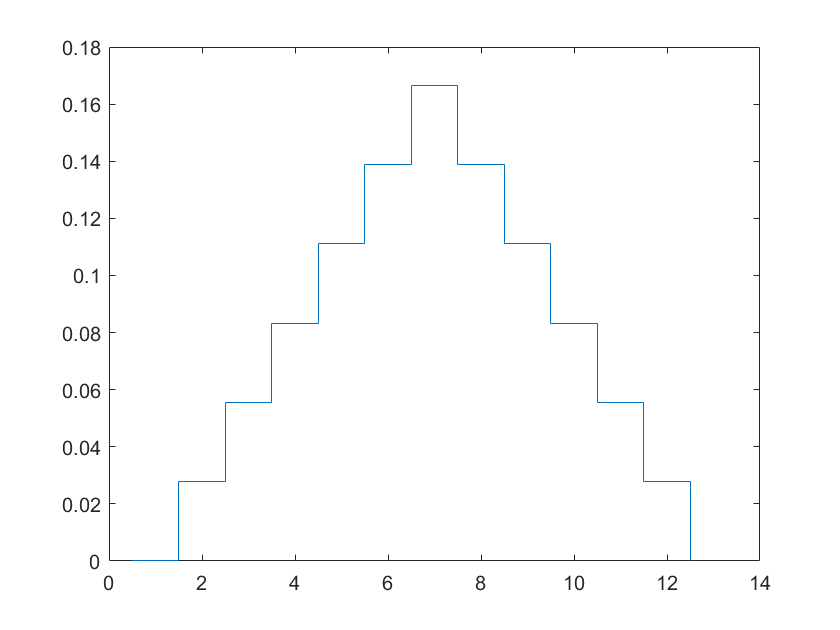

p_an = 1/36.*[0 1 2 3 4 5 6 5 4 3 2 1 0];
x_vec = [1 2 3 4 5 6 7 8 9 10 11 12 13]-0.5;
stairs(x_vec,p_an)

Numerical solution

The same results can be seen using Matlab's computational abilities.

p_iso = 1/6*ones(1,6); % vector of probabilities of rolling each #
p_num = conv(p_iso,p_iso); % convolutes 2 probability vectors
stairs(x_vec,[0 p_num 0])

The plots for the numerical and analytical solutions are identical.

3. Calculating mean and variance of the distribution above.


$$\textrm{Mean}=\sum_x x\cdot P\left(x\right)$$


sum_vals = [2:12];
mean_2dice = sum_vals*p_num';
disp(mean_2dice)

     7




$$\textrm{Variance}=\left\langle x^2 \right\rangle -\left\langle x{\left.\right\rangle }^2 \right.$$


Compute $\left\langle x^2 \right\rangle$:

avg_squares = mean(sum_vals.^2);
var_2dice = avg_squares-mean_2dice.^2;
disp(var_2dice)

    10



These values are within reasonable limits. The mean makes sense based on the plots above (symmetric about 7).

3. Calculate the average of 10 dice.

I do this by convolving the probabilities of outcomes for 1 die nine times, and then divide the x-axis of this distribution by 10 to get the average.

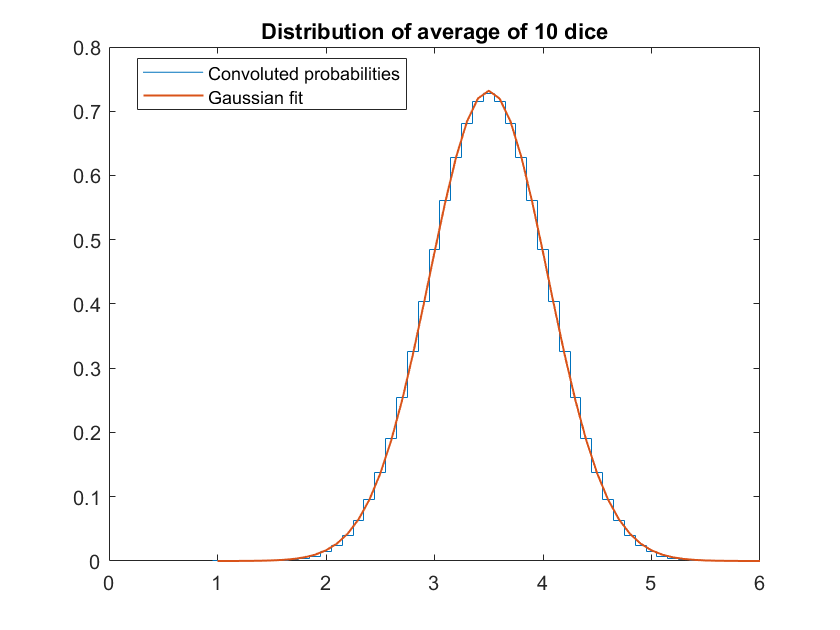

p_temp = p_iso;
for j=1:9
    p_temp = conv(p_iso,p_temp);
end
x_10avg = linspace(1,6,length(p_temp));
[max_val,max_index] = max(p_temp);
p_10avg = 10*p_temp;
stairs(x_10avg-0.05,p_10avg)
hold on
pd = makedist('Normal','mu',x_10avg(max_index),'sigma',0.545);
plot(x_10avg,pdf(pd,x_10avg),'LineWidth',1)
title('Distribution of average of 10 dice')
legend('Convoluted probabilities','Gaussian fit','Location','best')
hold off

The probabilities computed from the convolution looks like a good fit with a Gaussian distribution. To further check this, I make a log plot below.

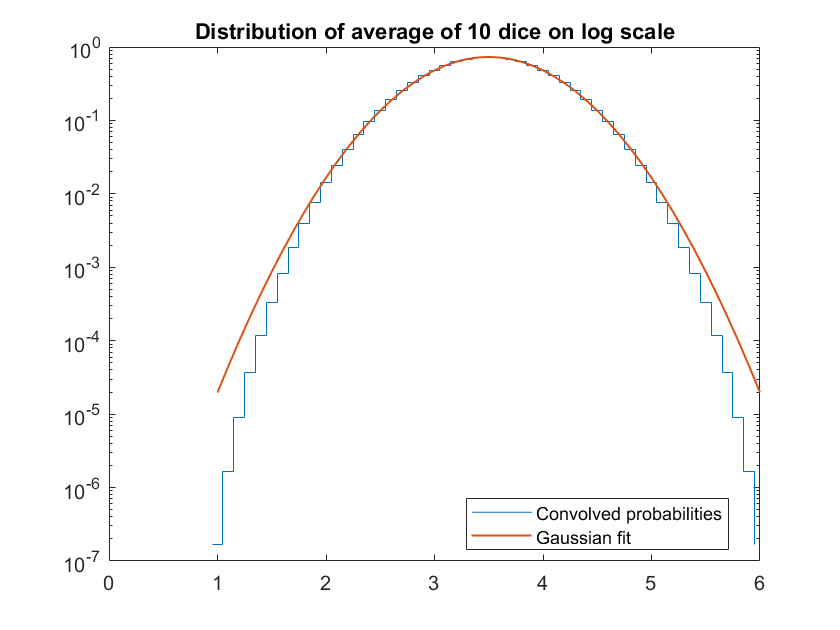

stairs(x_10avg-0.05,p_10avg)
hold on
pd = makedist('Normal','mu',x_10avg(max_index),'sigma',0.545);
plot(x_10avg,pdf(pd,x_10avg),'LineWidth',1)
set(gca,'YScale','log')
title('Distribution of average of 10 dice on log scale')
legend('Convolved probabilities','Gaussian fit','Location','best')
hold off

The log plot gives me a better idea of what is going on at the tails. The convoluted results agree closely with the Gaussian fit near the mean but drops off faster at the tails. It does still look like a parabola, though, and therefore the Gaussian approximation is appropriate.

5. Show that the sum and average of a Gaussian distribution is also Gaussian.

I create a standard Gaussian distribution below and convolve it 4 times. I compare the plots of the original, convolved and averaged distributions.

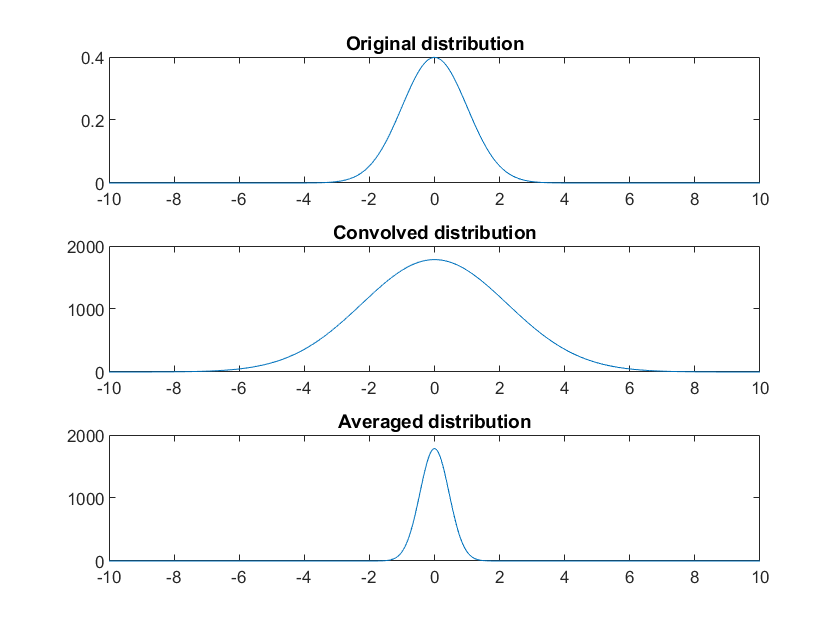

clear all; close all; clc
x_test = linspace(-10,10,201);
pd_test = normpdf(x_test);

figure
subplot(3,1,1)
plot(x_test,pd_test)
title('Original distribution')

subplot(3,1,2)
temp_test = pd_test;
avg_test = pd_test;
conv_count = 4;
for j=1:conv_count
    temp_test = conv(pd_test,temp_test,'same');
    avg_test = conv(pd_test,avg_test);
end
plot(x_test,temp_test)
title('Convolved distribution')

subplot(3,1,3)
x_testavg = linspace(-10,10,(conv_count+1)*201-conv_count);
plot(x_testavg,avg_test)
title('Averaged distribution')

The convolved distribution is wider and the averaged distribution is narrow than the original one.

I plot all the distributions on a log scale to verify that they exhibit the parabolic shape characteristic of a Gaussian distribution.

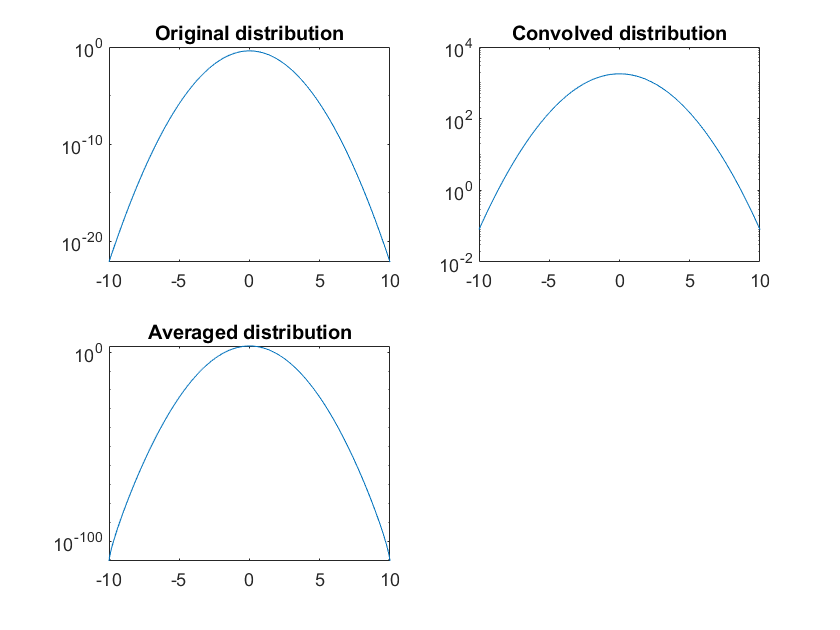

figure
subplot(2,2,1)
plot(x_test,pd_test)
set(gca,'YScale','log')
title('Original distribution')

subplot(2,2,2)
plot(x_test,temp_test)
set(gca,'YScale','log')
title('Convolved distribution')

subplot(2,2,3)
plot(x_testavg,avg_test)
title('Averaged distribution')
set(gca,'YScale','log')

These plots have the required shape, so I confirm that they are all Gaussian distributions.

Qualitatively, the standard deviation of the sum increases, and that of the average decreases, as compared to the original distribution.

**Explore what this means for integrating a signal over time.**

I'm not sure what this question means but I'll give it a shot: When we integrate a signal over time, we are doing a sum, so the range of possible values that the resulting signal can take increases, as does its standard deviation. However, we can average the signal over a particular time period to obtain a distribution that is narrower than the original one and has a smaller standard deviation.